# Bifurcation and Chaos

The phenomena of period doubling and chaos may be observed when a numerical  method is used to approximate the solution to an initial value problem for a  nonlinear differential equation. Consider the logistic model


$$\frac{\textrm{dp}}{\textrm{dt}}=10p\left(1-p\right),$$
    
$$p\left(0\right)=0\ldotp 1$$


Solve the initial value problem and show that the solution 𝑝(𝑡) approaches 1 as 𝑡 → ∞. Sketch the direction field for the differential equation, and plot the solution on the same graph as the direction field.

clear all 
close all
% Direction field
pprime = @(t,p) 10.*p.*(1-p);
% t goes from a to b
% p goes from c to d
a = 0; b=6;
c = 0; d=3;
h = 0.25;


figure

plotd(pprime,a,b,c,d,h);
t = a:h:b;
A = 10; p1 = 1; p0 = 0.1;
p = p0*p1./(p0+(p1-p0).*exp(-A*p1*t));

% plot on same window
hold on
plot(t,p)

## Perform 40 iterations of Euler’s method 

Describe the end behavior of the results for the following step sizes: 

- ℎ = 0.16, 

- ℎ = 0.23,

- ℎ = 0.25, 

- ℎ = 0.3. 

Plot the approximations on the same graph as the direction field and exact  answer. 

%eulers method
h = 0.16

h =    0.160000000000000


[t, p_eulers, ~, table] =eulers(pprime,0,h*40,p0,h);
table

table = 41×3 table
           x              y                     f          
          ____    _________________    ____________________

    0        0                  0.1                     0.9
    1     0.16                0.244                 1.84464
    2     0.32            0.5391424         2.4846787252224
    3     0.48    0.936690996035584       0.593009739814495
    4     0.64      1.0315725544059      -0.325693805976171
    5      0.8    0.979461545449716       0.201166264349698
    6     0.96     1.01164814774567      -0.117838270915727
    7     1.12    0.992794024399151      0.0715404951648854
    8     1.28     1.00424050362553     -0.0425848549653124
    9     1.44    0.997426926831083      0.02566

plot(t,p_eulers)

h = 0.23

h =    0.230000000000000


[t, p_eulers,~,table] =eulers(pprime,0,h*40,p0,h);
table

table = 41×3 table
           x              y                    f        
          ____    _________________    _________________

    0        0                  0.1                  0.9
    1     0.23                0.307              2.12751
    2     0.46            0.7963273      1.6219013127471
    3     0.69     1.16936460193183    -1.98048970319361
    4     0.92    0.713851970197302     2.04267334842732
    5     1.15     1.18366684033559    -2.17400348574444
    6     1.38    0.683646038614365     2.16274132501251
    7     1.61     1.18107654336724    -2.13865257925072
    8     1.84    0.689186450139578     2.14208487083585
    9     2.07     1.18186597043182    -2.14941201632932
    10 

plot(t,p_eulers)

h = 0.25

h =    0.250000000000000


[t, p_eulers,~,table] =eulers(pprime,0,h*40,p0,h);
table

table = 41×3 table
           x              y                    f        
          ____    _________________    _________________

    0        0                  0.1                  0.9
    1     0.25                0.325              2.19375
    2      0.5            0.8734375      1.1054443359375
    3     0.75     1.14979858398437    -1.72238199748099
    4        1    0.719203084614128     2.01950007695651
    5     1.25     1.22407810385326    -2.74289100479728
    6      1.5    0.538355352653938     2.48528866922792
    7     1.75     1.15967751996092    -1.85174430341787
    8        2     0.69674144410645     2.11292804170909
    9     2.25     1.22497345453372    -2.75586509778558
    10 

plot(t,p_eulers)

h = 0.3

h =    0.300000000000000


[t, p_eulers,~,table] =eulers(pprime,0,h*40,p0,h);
table

table = 41×3 table
           x             y                    f         
          ___    _________________    __________________

    0       0                  0.1                   0.9
    1     0.3                 0.37                 2.331
    2     0.6               1.0693    -0.741024899999999
    3     0.9           0.84699253      1.29596184124199
    4     1.2      1.2357810823726      -2.9137380117739
    5     1.5    0.361659678840426      2.30861955541466
    6     1.8     1.05424554546482    -0.571881246676001
    7     2.1    0.882681171462024      1.03555121008453
    8     2.4     1.19334653448738     -2.30729416885664
    9     2.7     0.50115828383039      2.49998658378568
    10 

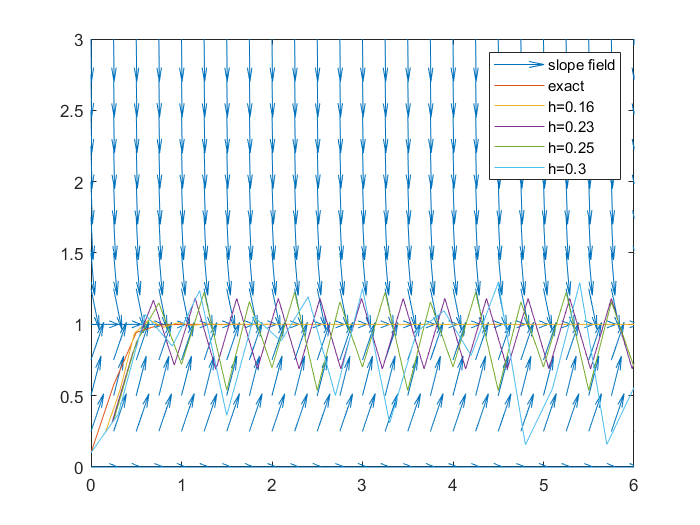

plot(t,p_eulers)

xlim([a b])
ylim([c d])
legend('slope field', 'exact', 'h=0.16', 'h=0.23','h=0.25','h=0.3')

hold off

## Construct the bifurcation diagram

- Beginning at ℎ = 0.16, compute the sequence $\left(p_n \right)$ using 230 iterations of Euler’s method. 

- Beginning at n = 201, plot the next 30 values. 

- Increment ℎ by 0.001 to 0.181 and repeat until ℎ = 0.3.

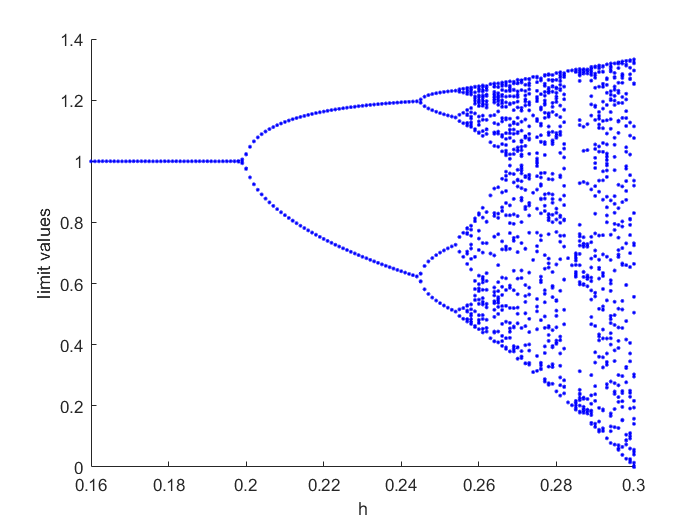

% bifurcation
plotb(pprime,p0,0.16,0.3,0.001)